%% =========================================================
% Monthly HWM14 + conservative seasonally-modulated F10.7 correction
% Based on CHAMP/GOCE paper conclusions:
% - seasonal cycle dominates
% - solar activity influence on wind is secondary
% - use small smooth solar correction only
%% =========================================================

clear; clc;

%% --- Configuration ---
lat = 0;
lon = 0;
altitudes = [200; 225; 250; 275; 300] * 1000;   % meters
alt_km = reshape(altitudes/1000, 1, []);

file_path = "C:\Users\jorda\OneDrive - Massachusetts Institute of Technology\Documents\Summer 26\space_weather_daily_may_1996_2026.csv";

%% --- Read input table ---
sw = readtable(file_path, 'VariableNamingRule', 'preserve');
sw.Date = datetime(sw.Year, sw.Month, sw.Day, 'TimeZone', 'UTC');

%% --- Timeline ---
t_start = datetime(1996, 5, 1, 12, 0, 0, 'TimeZone', 'UTC');
t_end   = datetime(2026, 5, 1, 12, 0, 0, 'TimeZone', 'UTC');
time_vector = (t_start : days(1) : t_end)';

%% --- Sizes ---
num_times = numel(time_vector);
num_alts  = numel(altitudes);

zonal_wind      = zeros(num_times, num_alts);
meridional_wind = zeros(num_times, num_alts);
delta_zonal     = zeros(num_times, num_alts);
delta_merid     = zeros(num_times, num_alts);

%% --- Time prep ---
doy = day(time_vector, 'dayofyear');
[H, M, S] = hms(time_vector);
sec_past_midnight = H*3600 + M*60 + S;
time_dates = dateshift(time_vector, 'start', 'day');

phi = 2*pi*(doy / 365.25);

%% --- Match dates to space weather file ---
[isFound, idxSW] = ismember(time_dates, sw.Date);

if ~all(isFound)
    warning('%d dates not found in CSV.', sum(~isFound));
end

%% --- Ap series ---
ap_series = nan(num_times,1);
ap_series(isFound) = sw.("Ap_daily")(idxSW(isFound));

if any(isnan(ap_series))
    warning('%d Ap values missing. Filling with 15.', sum(isnan(ap_series)));
    ap_series(isnan(ap_series)) = 15;
end

%% --- F10.7 series ---
f107_daily_all = sw.("F107_adj");

% Use 81-day running mean only, consistent with smoother solar forcing
f107_81_all = movmean(f107_daily_all, 81, 'omitnan');

f107_81 = nan(num_times,1);
f107_81(isFound) = f107_81_all(idxSW(isFound));

if any(isnan(f107_81))
    warning('%d F10.7 values missing. Filling with 150.', sum(isnan(f107_81)));
    f107_81(isnan(f107_81)) = 150;
end

F107_ref = 150;

%% --- Conservative altitude-dependent solar sensitivity ---
% Reduced compared to previous version because the paper indicates:
% solar activity effect on wind is modest relative to seasonal structure.
%
% Units: m/s per sfu
%
% Solar minimum-to-maximum excursion ~100 sfu should produce
% only ~5-15 m/s correction, not tens of m/s larger than the base pattern.

a0_zonal = reshape(interp1([200 300], [0.05 0.10], alt_km, 'linear', 'extrap'), 1, []);
a0_merid = reshape(interp1([200 300], [0.03 0.07], alt_km, 'linear', 'extrap'), 1, []);

% Seasonal modulation of solar sensitivity
a1_zonal = 0.20 * a0_zonal;
a2_zonal = 0.10 * a0_zonal;

a1_merid = 0.20 * a0_merid;
a2_merid = 0.10 * a0_merid;

%% --- Run HWM14 daily + conservative F10.7 correction ---
fprintf('Processing %d daily HWM14 evaluations...\n', num_times);

Processing 10958 daily HWM14 evaluations...


tic
for i = 1:num_times
    lat_input = repmat(lat, num_alts, 1);
    lon_input = repmat(lon, num_alts, 1);
    day_input = repmat(doy(i), num_alts, 1);
    sec_input = repmat(sec_past_midnight(i), num_alts, 1);
    ap_input  = repmat(ap_series(i), num_alts, 1);

    [u, v] = atmoshwm(lat_input, lon_input, altitudes, ...
                      'day',     day_input, ...
                      'seconds', sec_input, ...
                      'apindex', ap_input, ...
                      'model',   'total');

    % Force row vectors
    u_base = reshape(u, 1, []);
    v_base = reshape(v, 1, []);

    s1 = sin(phi(i));
    c1 = cos(phi(i));

    % Smooth seasonal sensitivity to solar flux
    A_zonal = a0_zonal + a1_zonal .* s1 + a2_zonal .* c1;
    A_merid = a0_merid + a1_merid .* s1 + a2_merid .* c1;

    dF = f107_81(i) - F107_ref;

    dv = A_zonal .* dF;
    du = A_merid .* dF;

    zonal_wind(i,:)      = v_base + dv;
    meridional_wind(i,:) = u_base + du;

    delta_zonal(i,:)     = dv;
    delta_merid(i,:)     = du;
end
toc

Elapsed time is 34.002454 seconds.



%% --- Monthly averaging ---
month_vector = dateshift(time_vector, 'start', 'month');
[G, month_list] = findgroups(month_vector);

n_months = numel(month_list);

zonal_monthly      = zeros(n_months, num_alts);
merid_monthly      = zeros(n_months, num_alts);
delta_zonal_month  = zeros(n_months, num_alts);
delta_merid_month  = zeros(n_months, num_alts);

for k = 1:num_alts
    zonal_monthly(:,k)     = splitapply(@mean, zonal_wind(:,k), G);
    merid_monthly(:,k)     = splitapply(@mean, meridional_wind(:,k), G);
    delta_zonal_month(:,k) = splitapply(@mean, delta_zonal(:,k), G);
    delta_merid_month(:,k) = splitapply(@mean, delta_merid(:,k), G);
end

f107_81_monthly = splitapply(@mean, f107_81, G);
ap_monthly      = splitapply(@mean, ap_series, G);

%% --- Monthly anomalies (remove calendar-month climatology) ---
zonal_anom = zeros(size(zonal_monthly));
merid_anom = zeros(size(merid_monthly));

month_num = month(month_list);

for k = 1:num_alts
    clim_z = zeros(12,1);
    clim_m = zeros(12,1);

    for m = 1:12
        idx = (month_num == m);
        clim_z(m) = mean(zonal_monthly(idx,k), 'omitnan');
        clim_m(m) = mean(merid_monthly(idx,k), 'omitnan');
    end

    for i = 1:n_months
        zonal_anom(i,k) = zonal_monthly(i,k) - clim_z(month_num(i));
        merid_anom(i,k) = merid_monthly(i,k) - clim_m(month_num(i));
    end
end

%% --- Print correction ranges ---
fprintf('\nMonthly mean solar correction ranges (zonal):\n');


Monthly mean solar correction ranges (zonal):


for k = 1:num_alts
    fprintf('%3d km: [%6.2f, %6.2f] m/s\n', alt_km(k), ...
        min(delta_zonal_month(:,k)), max(delta_zonal_month(:,k)));
end

200 km: [ -4.95,   4.08] m/s
225 km: [ -6.19,   5.11] m/s
250 km: [ -7.43,   6.13] m/s
275 km: [ -8.67,   7.15] m/s
300 km: [ -9.91,   8.17] m/s



fprintf('\nMonthly mean solar correction ranges (meridional):\n');


Monthly mean solar correction ranges (meridional):


for k = 1:num_alts
    fprintf('%3d km: [%6.2f, %6.2f] m/s\n', alt_km(k), ...
        min(delta_merid_month(:,k)), max(delta_merid_month(:,k)));
end

200 km: [ -2.97,   2.45] m/s
225 km: [ -3.96,   3.27] m/s
250 km: [ -4.95,   4.08] m/s
275 km: [ -5.94,   4.90] m/s
300 km: [ -6.93,   5.72] m/s


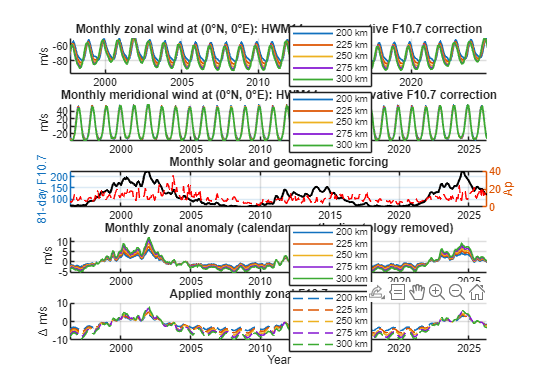


%% --- Plot ---
alt_labels = {'200 km','225 km','250 km','275 km','300 km'};
colors = lines(num_alts);

figure('Position',[100 100 1400 1000]);

subplot(5,1,1);
hold on;
for k = 1:num_alts
    plot(month_list, zonal_monthly(:,k), 'Color', colors(k,:), ...
        'LineWidth', 1.3, 'DisplayName', alt_labels{k});
end
title('Monthly zonal wind at (0°N, 0°E): HWM14 + conservative F10.7 correction');
ylabel('m/s');
grid on;
legend('Location','best');

subplot(5,1,2);
hold on;
for k = 1:num_alts
    plot(month_list, merid_monthly(:,k), 'Color', colors(k,:), ...
        'LineWidth', 1.3, 'DisplayName', alt_labels{k});
end
title('Monthly meridional wind at (0°N, 0°E): HWM14 + conservative F10.7 correction');
ylabel('m/s');
grid on;
legend('Location','best');

subplot(5,1,3);
yyaxis left
plot(month_list, f107_81_monthly, 'k', 'LineWidth', 1.5);
ylabel('81-day F10.7');

yyaxis right
plot(month_list, ap_monthly, 'r--', 'LineWidth', 1.1);
ylabel('Ap');

title('Monthly solar and geomagnetic forcing');
grid on;

subplot(5,1,4);
hold on;
for k = 1:num_alts
    plot(month_list, zonal_anom(:,k), 'Color', colors(k,:), ...
        'LineWidth', 1.2, 'DisplayName', alt_labels{k});
end
title('Monthly zonal anomaly (calendar-month climatology removed)');
ylabel('m/s');
grid on;
legend('Location','best');

subplot(5,1,5);
hold on;
for k = 1:num_alts
    plot(month_list, delta_zonal_month(:,k), '--', 'Color', colors(k,:), ...
        'LineWidth', 1.2, 'DisplayName', alt_labels{k});
end
title('Applied monthly zonal F10.7 correction');
ylabel('\Delta m/s');
xlabel('Year');
grid on;
legend('Location','best');